# Week 7 Homework

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

The problem statement is given as:

Rebuilding the Baxer Robot in MATLAB

Read a collection of papers and web links about Sawyer robot from re-think robotics (dissolved last year, unfortunately), and derive matlab code describing forward kinematics including angular and linear **velocities** and Jacobians. Basically I want x˙=Jq˙ of each link with all other frames.

After the submission deadline, two peer reviewers will be assigned to one reviewer to provide critiques to submissions. 

[https://rethinkrobotics.interaforum.com/topic/515-dh-parameters-for-sawyer/ (Links to an external site.)](https://rethinkrobotics.interaforum.com/topic/515-dh-parameters-for-sawyer/)

[https://www.researchgate.net/publication/299640286_Baxter_Kinematic_Modeling_Validation_and_Reconfigurable_Representation (Links to an external site.)](https://www.researchgate.net/publication/299640286_Baxter_Kinematic_Modeling_Validation_and_Reconfigurable_Representation)

[https://stackoverflow.com/questions/47102736/forward-kinematics-for-baxter (Links to an external site.)](https://stackoverflow.com/questions/47102736/forward-kinematics-for-baxter)

### Approach:

The approach is to first read through the provided links from Professor Hata and use the information provided in the links as well as from other available research-quality publications to come up with the DH parameters for the Baxter Robot. From this, the Jacobian that relates the velocity of the joint angles to the velocity of the end effector can be obtained. As it seems that Jacobians for each link are desired based on the problem statement, we can treat each link as an end effector and calculate the Jacobian for each "*ith-*link-as-an-end-effector" scenario with the help of an end effector selector drop down user-adjustable control. Finally, the selected end-effector's trajecotory and associated velocities (angular and linear) can be plotted.  

## Materials and Methods:

A moving coordinate frame has both angular and linear velocity. Linear velocity is associated to a moving point, while angular velocity is associated to a rotating frame. The linear velocity of a moving frame is the velocity of its origin. The angular velocity is related to the rate of rotation of a frame. 

The Jacobian is a matrix that relates the vector of individual joint velocities to the body velocity of the end effector:


$$\chi =J\dot{q}$$


For 3-dimensional analysis, the Jacobian is a 6x*n* matrix, with 3 rows that relate angular velocity of the individual joints to that of the end effector and 3 rows that relate linear velocity of the individual joints to that of the end effector. The *nth* column corresponds to the *nth* joint of the manipulator.

Written another way, in the indivual linear angular components, 


$$v=J_v \dot{q}$$



$$\omega =J_{\omega } \dot{q}$$


In general, each column of the Jacobian can take on one of two forms, one for a revolute joint and one for a prismatic joint. In this case, the columns are determined by the following relationships.

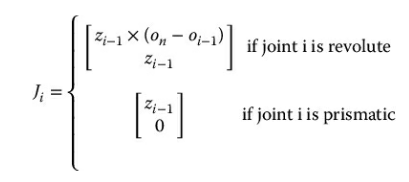

where $z_{i-1}$ is a 3x1 column vector for the z axis of the *ith *coordinate frame and $o_n \;\textrm{and}\;o_{i-1}$ are the end effector orgin 3x1 column vector and the *ith-1* origin of a manipulator coordinate frame. In both the revolute and the prismatic case shown above, the top row represents the linear velocity component of the Jacobian and the bottom row represents the angular velocity component of the Jacobian. 

Given this, it is possible to compute the Jacobian of any n-link manipulator and relate the velocities of the individual joint frames to that of the end effector frame. This proves useful when actuating the robot to achieve a specific end effector trajectory. 

Of particular interest is the Baxer Robot System, a 7DoF per-arm robot developed by Rethink Robotics.  The arms are symmetrical and consist entirely of rotational joints. In addtion, the "head" of the robot, a screen, has linkage with 2DoF (up, down, left, right) 

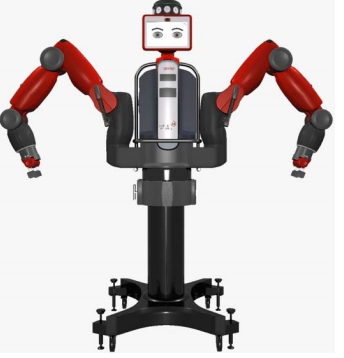 

Each arm consists of a 2DoF shoulder joint, a 2DoF elbow joint and a 3DoF wrist joint. There are no parallel joints nor are ther any 3 consective  joints sharing a common origin (i.e. no "spherical wrists") present on the robot. Both arms are identical in structure. 

As per Kumar et al. The Denavit-Hartenberg diagram and resulting DH table for one of the arms of the Baxter robot is given as:

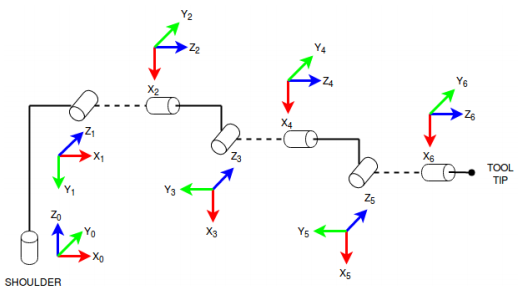

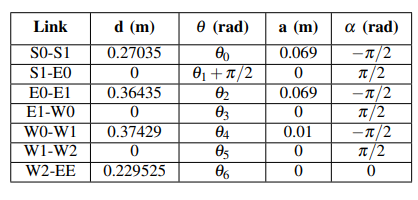

Using this forward kinematics information, we are able to construct a model for the Baxter robot arm and derive the Jacobian for each link by treating each link as an end effector and calculating its x, y and z angular and linear velocities for given individual joint velocities of previous links.  

## Results:

With Baxter's arms understood to be a 7-link serial manipulators, we can now model Baxter based on the information provided by Williams and Kumar et al. 

In modelling Baxter, we have chosen to model only a single arm as both arms are equivalent in configuration. While this does not take into account the possible interactions between the two arms (i.e. workspace, possible collisions etc), it should be sufficient for this exercise. 

We begin by defining `end_effector_select` as a drop-down control that evaluates to an integer from 1 to 7 to indicate which link number we are considering the "end-effector" for our Jacobian calculation. As the Baxter arm is a serial manipulator, the Jacobian that yields the velocity relationship between the individual joints and the *ith* joint should not be affected by joints after the *ith* joint. That is, the individual velocities of the *ith*+n joints should not effect the velocity of the *ith* joint.

%**************************************MAGIC BUTTON********************************************%
%End effector select - controls which link to consider end effector when calculating Jacobian 
%Changing this control setting re-runs everything to the end of the file and
%changes how the robot object baxter is defined.

end_effector_select = 7;

%NOTE:Some minor plotting issues may arise as end_effector_select is
%changed. Known issue, and no idea why it happens. Just hit "Run" at the top to fix it.
%**********************************************************************************************%

disp("The end effector is chosen to be link " + end_effector_select);

The end effector is chosen to be link 7



syms 'a%d' 'alpha%d' 'd%d' 'theta%d' [1 7]

%DH table as per Kumar et al.
dh = [
    a1  -pi/2   d1    theta1;
    0    pi/2   0     theta2+pi/2;
    a3  -pi/2   d3    theta3;
    0    pi/2   0     theta4;
    a5  -pi/2   d5    theta5;
    0    pi/2   0     theta6;
    0    0      d7    theta7;
    ]

$$dh = \left(\begin{array}{cccc} a_{1} & -\frac{\pi }{2} & d_{1} & \theta_{1}\\ 0 & \frac{\pi }{2} & 0 & \theta_{2}+\frac{\pi }{2}\\ a_{3} & -\frac{\pi }{2} & d_{3} & \theta_{3}\\ 0 & \frac{\pi }{2} & 0 & \theta_{4}\\ a_{5} & -\frac{\pi }{2} & d_{5} & \theta_{5}\\ 0 & \frac{\pi }{2} & 0 & \theta_{6}\\ 0 & 0 & d_{7} & \theta_{7} \end{array}\right)$$


[a, alpha, d, theta]=initialize_dh_params(dh, a, alpha, d, theta);
[full_xform, successive_frame_xforms,base_to_frame_xforms] = create_A_0_n_matrix(a,alpha,d,theta);

%get base-to-end-effector transform based on end_effector_select chosen
simplify(base_to_frame_xforms(:,:,end_effector_select))

Above, we use the DH parameter table defined by Kumar et al. for the Baxter arm to describe the inter-frame relationships between the links. The `create_A_0_n_matrix`  is then used to compute the inter-frame transforms (the base to link 7 "full" transform, the *ith* to *jth *frame successive transforms and the base to *ith* frame transforms. We care primarily about the `base_to_frame_xforms` output of the afforementioned function and the `end_effector_select` value that gives us the base to *ith* frame transform from the array, as the *ith* frame is now considered the end-effector.

The function `create_A_0_n_matri`x was created largely by Ezekiel Flaton and computes each individual successive 4x4 homogeneous$A_j^i$ matrix, the full transformation matrix $A_n^0$ and the base-to-frame matricies $A_i^0$. It takes the dh parameters arrays $a,\alpha ,d,\theta$  as inputs and outputs the A matricies in arrays. The function calculates the number of links in the DH parameter arrays and assigns size this to the loop counter variable.

`create_A_0_n_matrix` calls a function `create_dh_matrix `in a loop starting at the $A_i^0$ matrix to compute the 4x4 standard DH matrix that transforms from one coordinate frame to the next for each link. It stores the resulting matrix in an array `A_i_array`. The `dh_matrix` is then multiplied by `intermediate_matrix,`which has stored the last matrix calculated in the loop, to get the transformation from the base frame to the *ith* coordinate frame. This base-to-frame transformation is stored in the `A_0_i_matrix` array. Finally, the last matrix held in `dh_intermediate_matrix` is assigned to the output `A_0_n` which represents the transformation from the base frame to the end effector.

With the DH parameters and the a, alpha, d and theta arrays defined, we can now calculate the Jacobian that relates the individual joint velocities to the angular and linear velocities of the *ith* link.


%Array of joint types for create_jacobian
joint_types = ['r','r','r', 'r', 'r', 'r', 'r'];

%Create Jacobian using the pre-made function
jacobian = create_jacobian(a(1:end_effector_select), alpha(1:end_effector_select), d(1:end_effector_select), theta(1:end_effector_select), joint_types);

simplify(jacobian) % symbolic jacobian - can be uncommented/commented out 



%actual link lengths from Kumar et al.
d1 = 0.27035;
d3 = 0.36435;
d5 = 0.37429;
d7 = 0.229525; 
a1 = 0.069;
a3= 0.069;
a5 = 0.01;
theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = 0;
theta5 = 0;
theta6 = 0;
theta7 = 0;

%Jacobian for Baxter w/ values sub'd in
jacobian_w_link_lengths = double(subs(jacobian))

jacobian_w_link_lengths =          0   -0.0790         0   -0.0100         0         0         0
    1.0372         0    0.0790         0    0.0100         0         0
         0   -0.9682         0   -0.6038         0   -0.2295         0
         0         0    1.0000         0    1.0000         0    1.0000
         0    1.0000         0    1.0000         0    1.0000         0
    1.0000         0         0         0         0         0         0


The function `create_Jacobian` was also largely developed by Ezekiel Flaton and is used to calculate the Jacobian matrix of a manipulator when passed the manipulator's DH parameters $a,\alpha ,d,\theta$ and an array describing each joint's type, be it revolute or prismatic. 

Given the DH parameter information and joint type, the function first calls `create_A_0_n_matrix` which creates and outputs the full homogeneous transform from the base frame to the end effector, $A_n^0$, an array of successive matrix transformations that represent the transformation from one frame to the next (i.e. the $A_j^i$'s) and an array of matrix transformations from the base frame to the given frames (i.e. the $A_i^0$'s). From the calculation of the $A_i^0$ matricies, the Jacobian can be gotten from the information contained within these matricies. 

**For a revolute or type 'r' joints,** this is accomplished  by first obtaining the $z_{i-1}$ vectors for each joint's coordinate frame. This is equivalent to vector represented by third column, rows 1-3 of each $A_i^0$ matrix, which is itself equivalent to multiplying the 3x3 rotational component of the $A_i^0$ matrix by the z-unit vector $k=\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$.

Then, the location of the origins of each coordinate frame arw obtained by computing the differences between the end effector coordinate frame origin `o_n` and previous origins `o_i_minus1`. The end effector origin `o_n` and the local coordinate frames `o_n_minus1` are gotten from the displacement component (rows 1-3, column 4) of the $A_n^0$ and $A_i^0$ transformation matricies, respectively.  

Finally, the Jacobian for each revolute joint can be calculated as `cross(z_i_minus1,o_difference)`, the cross product of the $z_{i-1}$ coordinate frame vector and the difference between the $o_n$ and $o_{i-1}$ frame origins, for linear velocities. For angular velocities of revolute joints, the Jacobian elements are just $z_{i-1}$.

**For a prismatic or type 'p' joints**, the linear velocity component is just $z_{i-1}$ and is calculated as the multiplication of the rotational component of the $A_i^0$ matrix with the z-unit vector $k$ and there is no angular velocity component of the Jacobian (i.e. $J_{\omega } =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$)

The final line of the function, `jacobian(:,i)=[velocities;omega],` assigns the 6x1 Jacobian mapping for the *ith* joint variable to the *ith* column of the jacobian matrix, with the top 3 rows being the linear velocity components and the bottom 3 rows being the angular velocity components.

After the jacobian is created, we can display the symbolic Jacobian as well as plug in the values for the link lengths and offsets given by Kumar et al using the `subs` function.

With the Jacobian defined numerically, we can use the MATLAB robotics toolbox to build a model of the Baxter manipulator arm.

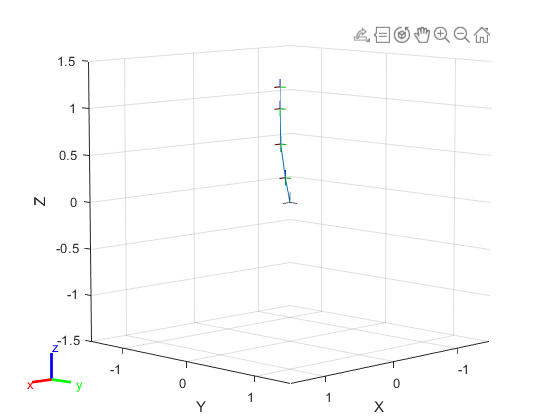

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Full sub'd in DH table for 7-link baxter - needed for rigid body robot
%construction as per my "build-a-robot" function
dh_params_w_link_lengths = double(subs(dh));

%create array of joint type strings
joint_array_baxter=strings(1,end_effector_select);
for i = 1:length(joint_array_baxter)
    joint_array_baxter(i) = 'revolute';
end

%instantiate baxter object
baxter = robotics.RigidBodyTree();

%run our build-a-robot function
construct_rigid_body_robot(baxter,dh_params_w_link_lengths,joint_array_baxter);

baxter

baxter =   rigidBodyTree with properties:

     NumBodies: 7
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'body1'  'body2'  'body3'  'body4'  'body5'  'body6'  'body7'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


We first substitute in actual values into the symbolic dh_params table and define a new variable `dh_params_w_link_lengths`. Then, we use `end_effector_select` to create an array of joint type strings for RigidBodyTree robot object definition. Here, we create a loop that fills a string array with all "revolute" strings based on the end-effector link chosen. 

We define our robot object to be `baxter` using the robotics toolbox. Then, using the `construct_rigid_body_robot` function we pass the `baxter` object, the numerically defined DH table and the array of joint type strings to define baxter as an *ith*-link serial robot based on the size of the `joint_array_type` passed to it.

`construct_rigid_body_robot` was a function created by the author to automate the routine to define a serial rigid body robot object using the MATLAB robotics toolbox. The function first uses the length of the joint type array to calculate the number of links that need to be created and instantiates the number of required bodies and joints. Then, from the DH parameter table passed to the function, the `setFixedTransform` function assigns the appropriate *ith* DH table row to the *ith* link joint. With the inter-joint transformations defined, the bodies are then associated to their appropriate joints. Finally, the robot is constructed using the `addBody` function to specify the connections between successive bodies. The robot is then set to the home configuration and is finally displayed.

With the Baxter arm defined as a rigid body robot, we can define the Jacobian for each pose we put the robot in using the built-in `geometricJacobian` function. With the Jacobian for a desired pose defined, we can calculate the end-effector velocities based on the individual joint velocities.

First, we define our trajectory and calculate our individual joint velocities with the function `trapveltraj` to create trapezoidal motion profiles for each individual joint. 

Here, we have chosen to use the joint limits (in degrees) for Baxter provided by Williams to set waypoints of motion (expressed in radians) for the individual joints by creating arrays of linearly spaced out joint angles (using `linspace`). With these waypoints defined, we can pass the indiviudal waypoint arrays to `trapveltraj` along with an arbitrary scalar value of data points to obtain trapezoidal position and velocity profiles for each individual joint based on the waypoints. 

%joint limits in degrees as per Williams.
theta1_lim = [51 -141];
theta2_lim = [60 -123];
theta3_lim = [173 -173];
theta4_lim = [150 -3];
theta5_lim = [175 -175];
theta6_lim = [120 -90];
theta7_lim = [175 -175];

%define number of points in trapezoidal trajectory
traj_size = 501;

%positions by way of waypoints
wpts1 = linspace(theta1_lim(1), theta1_lim(2), 10)*pi/180; %way points for joint 1
wpts2 = linspace(theta2_lim(1), theta2_lim(2), 10)*pi/180; %way points for joint 2
wpts3= linspace(theta3_lim(1), theta3_lim(2), 10)*pi/180; %way points for joint 3
wpts4 = linspace(theta4_lim(1), theta4_lim(2), 10)*pi/180; %way points for joint 4
wpts5 = linspace(theta5_lim(1), theta5_lim(2), 10)*pi/180; %way points for joint 5
wpts6 = linspace(theta6_lim(1), theta6_lim(2), 10)*pi/180; %way points for joint 6
wpts7 = linspace(theta7_lim(1), theta7_lim(2), 10)*pi/180; %way points for joint 7

%Pos and Vel for joints
[q1, qd1, qdd1, tvec1, pp1] = trapveltraj(wpts1, traj_size); % Pos and vel for joint1
[q2, qd2, qdd2, tvec2, pp2] = trapveltraj(wpts2, traj_size); % Pos and vel for joint2
[q3, qd3, qdd3, tvec3, pp3] = trapveltraj(wpts3, traj_size); % Pos and vel for joint3
[q4, qd4, qdd4, tvec4, pp4] = trapveltraj(wpts4, traj_size); % Pos and vel for joint4
[q5, qd5, qdd5, tvec5, pp5] = trapveltraj(wpts5, traj_size); % Pos and vel for joint5
[q6, qd6, qdd6, tvec6, pp6] = trapveltraj(wpts6, traj_size); % Pos and vel for joint6
[q7, qd7, qdd7, tvec7, pp7] = trapveltraj(wpts7, traj_size); % Pos and vel for joint7

Before we begin calculating velocities, as a curious and illustrative point, we can set `baxter` to the home configuration and print out the geometric Jacobian in the home configuration. We can compare this matrix to the calculated Jacobian matrix using `create_jacobian`. `end_effector_body` is a variable that holds a string defining the body that has been selected as the end effector based on `end_effector_select` and will be reused when calculating the end-effector velocities in the code to follow.

%Set config to homeConfiguration
config = homeConfiguration(baxter);

%define end effector for use by geometricJacobian
end_effector_body = sprintf("body%d",end_effector_select);

%Get Jacobian for home config
geometricJacobian(baxter,config, end_effector_body)

ans =          0         0         0         0         0         0         0
         0    1.0000         0    1.0000         0    1.0000         0
    1.0000    0.0000    1.0000    0.0000    1.0000    0.0000    1.0000
         0    0.9682         0    0.6038         0    0.2295         0
    0.1480    0.0000    0.0790    0.0000    0.0100         0         0
         0   -0.0790         0   -0.0100         0         0         0


With position and velocity trajectories for the individual joints now defined, we are ready to compute the end effector velocities. 

%initialize arrays for memory effeciency while looping - all 0's
x_omega_robot_chi = zeros(1,traj_size);
y_omega_robot_chi = zeros(1,traj_size);
z_omega_robot_chi = zeros(1,traj_size);
x_v_robot_chi =zeros(1,traj_size);
y_v_robot_chi = zeros(1,traj_size);
z_v_robot_chi = zeros(1,traj_size);
end_effector_x = zeros(1,traj_size);
end_effector_y = zeros(1,traj_size);
end_effector_z = zeros(1,traj_size); 

%create an matrix (or array of arrays) of the positions
q_array = [q1;q2;q3;q4;q5;q6;q7]; %rows = joint#, columns=positions

%loop to set joint positions, calc jacobian and get chi for each position /
%joint velocity setting
for i = 1:traj_size
    
    %Nested loop sets the ith joint position for each jth link in play from
    %link 1 to the end effector defined by end_effector_select
    for j = 1:end_effector_select
        config(j).JointPosition = q_array(j,i);
    end
    
    %Capture end effector position
    end_effector_xform = getTransform(baxter,config,end_effector_body);
    end_effector_pt = end_effector_xform*[0;0;0;1]; %get 4th column aka position
    
    %get jacobian
    %n.b. jacobian is OMEGA at top rows and V at bottom rows
    robot_jacobian = geometricJacobian(baxter,config,end_effector_body);
    
    %Define current qd_array
    qd_array =[qd1(1,i);qd2(1,i);qd3(1,i);qd4(1,i);qd5(1,i);qd6(1,i);qd7(1,i)];
    %compute end effector velocities from individual joint velocities
    %size of qd_array is based on end effector selection
    robot_chi= robot_jacobian*qd_array(1:end_effector_select);
    
    %store omega (angular) and v (linear) coordinates
    x_omega_robot_chi(1,i) = robot_chi(1,1);
    y_omega_robot_chi(1,i) = robot_chi(2,1);
    z_omega_robot_chi(1,i) = robot_chi(3,1);
    x_v_robot_chi(1,i) = robot_chi(4,1);
    y_v_robot_chi(1,i) = robot_chi(5,1);
    z_v_robot_chi(1,i) = robot_chi(6,1);
    end_effector_x(i) = end_effector_pt(1,1);
    end_effector_y(i) = end_effector_pt(2,1);
    end_effector_z(i) = end_effector_pt(3,1);
end

As explained in the comments of the code, the above code first initializes the arrays that capture the end-effector positon data as well as the end-effector linear and angular velocity data for memory efficiency during calculation. The major loop of the code iterates through the individual joint positions held in the $q_i$ arrays and assigns those positions to the joints defined in the `config` construct. The 4x4 homogeneous transform from the base to the selected end-effector of `baxter` is then computed using the `getTransform` function. From this transform, the end-effector position data held in the 4th column of the homogeneous matrix is extracted by multiplying the matrix by an origin point vector and this data is captured in the `end_effector `x, y and z arrays. 

The minor nested *j* loop simply assigns an individual joint in the manipulator a position from the appropriate row and column based on the jth link (up to the chosen end effector) and current *ith* step in the trajectory, respectively.

Meanwhile, the Jacobian for the current config (i.e. the current "pose") can be calculated using the `geometricJacobian` function for the selected end-effector and stored as `robot_jacobian.` `robot_jacobian` can be multiplied by `qd_array`, the matrix of the individual joints' trapezoidal velocity trajectories, to yield the end effector's angular and linear velocities for the given step in the trajectory profile. The end effector velocities are stored as `robot_chi.` `robot_chi` can then be parsed for the x,y, and z linear and angular velocity components for the given step in the trajectory.

The end effector trajectory by position is then plotted: 

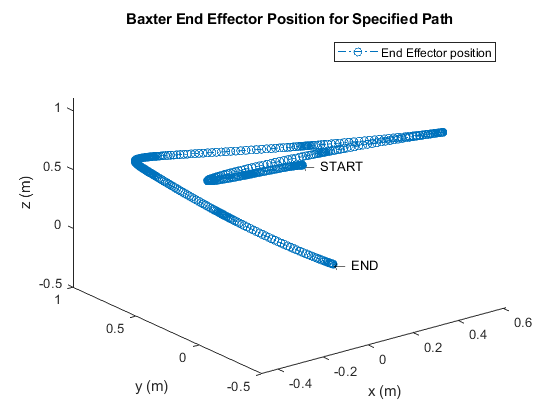

%plot end effector position
figure;
plot3(end_effector_x,end_effector_y,end_effector_z, '-.o');
legend('End Effector position','Location','northeast');
title('Baxter End Effector Position for Specified Path');
text(end_effector_x(1,1),end_effector_y(1,1),end_effector_z(1,1),"\leftarrow START");
text(end_effector_x(1,traj_size),end_effector_y(1,traj_size),end_effector_z(1,traj_size),"\leftarrow END");
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');

The linear velocity of the end effector is plotted:

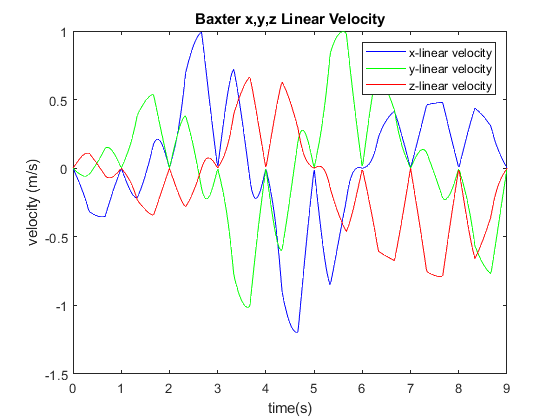

%plot linear velocity of end effector
figure;
plot(tvec1,x_v_robot_chi,'-b',tvec1,y_v_robot_chi,'-g',tvec1,z_v_robot_chi,'-r');
legend('x-linear velocity','y-linear velocity','z-linear velocity','Location','northeast');
xlabel('time(s)');
ylabel('velocity (m/s)');
title('Baxter x,y,z Linear Velocity');

And finally the angular velocity of the end effector is plotted:

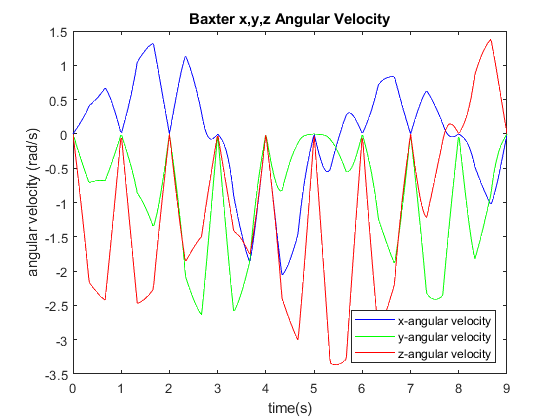

%plot angular velocity of end effector
figure;
plot(tvec1,x_omega_robot_chi,'-b',tvec1,y_omega_robot_chi,'-g',tvec1,z_omega_robot_chi,'-r');
xlabel('time(s)');
ylabel('angular velocity (rad/s)');
legend('x-angular velocity','y-angular velocity','z-angular velocity','Location','southeast');
title('Baxter x,y,z Angular Velocity');

## Discussion:

The Baxter robot arm was successfully modeled in MATLAB using both custom MATLAB functions as well as the classes, functions and structures provided by the MATLAB Robotics Toolbox. For the Baxter model created using the Robotics Toolbox, the end effector positon and velocities were successfully plotted. 

The ability to run simulations for several different defintions of the Baxter robot arm's end effector (that is, when individually considering each link as an end effector) provided an interesting perspective into how the number of links affects both the path/trajectory of the manipulator as well as insights into how the end-effector velocities vary depending on the number of links when holding the trajectory for each joint constant. In general, the end effector angular and linear velocities' complexity increases as more links are considered, as does the Jacobian that maps the individual joint velocities to the end effector velocities. Choosing links farther down in the kinemaic chain of the Baxter robot arm as the end effector increases the degrees of freedom of the robot arm and thus increases the complexity of the Jacobian. 

The choice of trajectory of the robot end effector was informed by the joint limits given in Williams and seemed like a natural choice to fully exercise the range of motion of the Baxter robot arm. The result of choosing the start and end points of the trajectory to be the joint limits resulted in exclusively circular or "corkscrew" end-effector paths. Further work with different trajectory paths may be done to offer more insight into how varying the choice of link to model as an end effector affects the behavior of the manipulator arm. A study of the operating range of motion of the arm would expand upon the work presented here in this assignment. Other topics related to the characterization of the Baxter robot arm such as its singularities, its forward and inverse dynamics and an analysis of Baxter models involving both arms are also worthy of exploration for future work.

One subtle discrepancy between the output of the `create_jacobian` function and the `geometricJacobian` function exists in the code above, particuarly for the link-7-as-end-effector case. After looking over both functions and their outputs, there is currently not a good explanation for this subtle discrepancy other than the fact that the calculation methods may differ somewhat. More work is needed to resolve this point.  

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 35-74) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- R.L. Williams II, “Baxter Humanoid Robot Kinematics”, Internet Publication, https://www.ohio.edu/mechanical-faculty/williams/html/pdf/BaxterKinematics.pdf, April 2017. 

- Akshay Kumar et al, “Baxter Humanoid Robot Kinematics”, Internet Publication,https://kumarakshay.me/images/mykdl/baxter-kdl-project.pdf

## Defined Functions

function r_matrix = create_rotation_matrix(x, y, z)
    % This function creates a rotation matrix using roll (z), pitch (y),
    % and yaw (x) angles
    r_x_matrix = [1 0 0 ; 0 cos(x) -sin(x) ; 0 sin(x) cos(x)];
    r_y_matrix = [cos(y) 0 sin(y); 0 1 0; -sin(y) 0 cos(y)];
    r_z_matrix = [cos(z) -sin(z) 0; sin(z) cos(z) 0; 0 0 1];
    r_matrix = r_z_matrix * r_y_matrix * r_x_matrix;
end

function h_matrix = create_homogenous_matrix(x,y,z,dx,dy,dz)
    r_matrix = create_rotation_matrix(x,y,z);
    d_vector = [dx; dy; dz];
    h_matrix = [r_matrix d_vector; 0 0 0 1];
end

function dh_matrix = create_dh_matrix(a, alpha, d, theta)
    dh_matrix = [
      cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
      sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
      0,          sin(alpha),           cos(alpha),             d;
      0,            0,                  0,                      1];
end

function [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta)
    % This function creates several dh transformation matrices and
    % multiplies them together to give one final transformation matrix
    % Inputs are 1xn matrices representing the dh params for each link
    % Output is a 4x4 dh matrix representing the ovrall transform for all
    % given links
    
    % Find the umber of links by finding the length of the array theta
    number_of_links = size(theta,2);
    % Ensure that the arrays for alpha, a, and d are the same size as theta
    if (size(alpha,2)==number_of_links)&&(size(a,2)==number_of_links)&&(size(d,2)==number_of_links)
        
        % Start off by creating a symbolic dh matrix that is 4x4xn
        % Each 4x4 matrix will represent 1 step of the transform and there
        % will be n transforms for the n links
        A_i_array = sym("dh_matrix_array", [4,4,number_of_links]);
        
        % Initialize an identity matrix to calculate the ifinal dh
        % transform on the fly
        dh_intermediate_matrix = eye(4,4);
        for i=1:number_of_links
            dh_matrix = create_dh_matrix(a(i), alpha(i), d(i), theta(i)); % Create the dh matrix for link i
            A_i_array(:,:,i) = dh_matrix; % Assign that dh_matrix to our 4x4xn matrix at index i
            dh_intermediate_matrix = dh_intermediate_matrix * dh_matrix; % Get the full transform up to this point
            A_0_i_array(:,:,i) = dh_intermediate_matrix;
        end
        A_0_n = dh_intermediate_matrix;
    else
        disp("Error with array sizes of inputs");
        A_0_n = "ERROR";
    end
    % Below is code to replace certain variables in the symbolic matrix and
    % get an output
    %     create_dh_handle = matlabFunction(dh_final_matrix);
    %     y = feval(create_dh_handle, theta(1),theta(2),theta(3));
end

function p = PlotHAxes(H, l, linespec, color)
    % This function comes courtesy of John Dong (2019 RBE 500)
    
    % Plot a set of axes of length l represented by the given homogeneous transformation matrix
    p(1) = plot3([H(1,4) H(1,4)+H(1,1)*l], [H(2,4) H(2,4)+H(2,1)*l], [H(3,4) H(3,4)+H(3,1)*l], ...
        linespec, 'color', color);
    p(2) = plot3([H(1,4) H(1,4)+H(1,2)*l], [H(2,4) H(2,4)+H(2,2)*l], [H(3,4) H(3,4)+H(3,2)*l], ...
     linespec, 'color', color);
    p(3) = plot3([H(1,4) H(1,4)+H(1,3)*l], [H(2,4) H(2,4)+H(2,3)*l], [H(3,4) H(3,4)+H(3,3)*l], ...
     linespec, 'color', color);
end

function [a, alpha, d, theta] = initialize_dh_params(dh_table, a, alpha, d, theta)
    for i=1:size(dh_table,1)
        a(i) = dh_table(i,1);
        alpha(i) = dh_table(i,2);
        d(i) = dh_table(i,3);
        theta(i) = dh_table(i,4);
    end
end

function plot_links(A_0_i_array, figure_object, linespec, color, limits, labels, my_title)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    % limits: 3x2 array containing x, y, and z axis limits
    % labels: 3x1 array containing x, y, z axis labels
    % my_title: string title of graph
    figure_object;
    num_of_links = size(A_0_i_array,3);
    dx_array = NaN(1, num_of_links);
    dy_array = NaN(1, num_of_links);
    dz_array = NaN(1, num_of_links);
    for i=1:num_of_links
        dx_array(i) = A_0_i_array(1,4,i);
        dy_array(i) = A_0_i_array(2,4,i);
        dz_array(i) = A_0_i_array(3,4,i);
    end
    dx_array = [0 dx_array];
    dy_array = [0 dy_array];
    dz_array = [0 dz_array];
    plot3(dx_array, dy_array, dz_array, linespec, "color", color);
    xlim(limits(1,:));
    ylim(limits(2,:));
    zlim(limits(3,:));
    xlabel(labels(1));
    ylabel(labels(2));
    zlabel(labels(3));
    title(my_title)
    grid on
    
end

function plot_coordinate_frames(A_0_i_array, figure_object, l, linespec, color)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % l: length of the coordinate axis lines
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    num_of_links = size(A_0_i_array,3);
    figure_object;
    for i=1:num_of_links
        double(A_0_i_array(:,:,i));
        PlotHAxes(A_0_i_array(:,:,i), l, linespec, color);
    end
    grid on
   
end

function jacobian = create_jacobian(a, alpha, d, theta, joint_type)
    debug = false;
    error = false;
    % Inputs:
    % a: array of a values from dh table
    % alpha: array of alpha values from dh table
    % d: array of d values from dh table
    % theta: array of theta values from dh table
    % joint_type: array of string values.  Each is either "r" or "p" for
    % revolute or prismatic
    [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta);
    num_of_links = size(A_0_i_array,3);
    jacobian = sym("dh_matrix_array", [6,num_of_links]);
    o_n = simplify(A_0_i_array(1:3,4,num_of_links));
    for i=1:num_of_links
        % Create 1 column in the Jacobian for each link
        if i == 1
            z_i_minus1 = [0;0;1];
            o_i_minus1 = [0;0;0];
        else
            z_i_minus1 = A_0_i_array(1:3,3,i-1);
            o_i_minus1 = A_0_i_array(1:3,4,i-1);
        end
        
        if joint_type(i) == "r"
            o_difference = o_n-o_i_minus1;
            velocities = cross(z_i_minus1, o_difference);
            omega = z_i_minus1;
        elseif joint_type(i) == "p"
            velocities = z_i_minus1;
            omega = [0;0;0];
        else
            disp("Error with joint types")
            error = true;
        end
        if debug, jacobian(:,i), end
        if debug, [velocities; omega], end
        jacobian(:,i) = [velocities; omega];
    end
    if error
        jacobian = "ERROR"
    end
end

function DH = genDHMatrixdeg(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in DEGREES for alpha and theta
DH = [
    cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta);...
    sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta);...
    0          sind(alpha)             cosd(alpha)            d;...
    0          0                      0                     1
    ];
end

function DH = genDHMatrix(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in RADIANS for alpha and theta
DH = [
    cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);...
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);...
    0          sin(alpha)             cos(alpha)            d;...
    0          0                      0                     1
    ];
end

function [J11det, J22det] = getSingularityEqns(Jacobian)
    % Inputs: A 6xn Jacobian matrix
    % Calculates 3x3 determinant of J11 quadrant and J22 quadrant of 6x6 Jacobian
    %if DOF of robot is <6, will either give J11 or J22 equation
    %other eqn should be 0.
    dofCount = size(Jacobian,2);
    if dofCount==1
        J11det = 0;
        J22det = 0;
    end
    if dofCount==2
        J11 = Jacobian(1:2,1:2);
        J11det = simplify(det(J11));
        J22det = 0;
    end
    if dofCount>=3
        J11 = Jacobian(1:3,1:3);
        J11det = simplify(det(J11));
        J22 = Jacobian(4:6,dofCount-2:dofCount);
        J22det = simplify(det(J22));
    end
end

function construct_rigid_body_robot(robot,dh_params,joint_type_array)
    %Constructs robot given a rigidBodyTree() object, dh parameter table and a joint type array 
    %joint type is either 'revolute' or 'prismatic' for each link
   
    %get number of links
    num_links = length(joint_type_array);
   
    %Define bodies and joints
    for i=1:num_links
        bodynum = sprintf("body%d",i);
        jointnum = sprintf("jnt%d",i);
        body(i) = robotics.RigidBody(bodynum);
        jnt(i) = robotics.Joint(jointnum,joint_type_array(i));
    end
    
    %Specify body-to-body transformations
    for i = 1:num_links
    setFixedTransform(jnt(i),dh_params(i,:),"dh");
    end
    
    %Associate bodies to joints
    for i = 1:num_links
        body(i).Joint = jnt(i);
    end
    
    %attach bodies together
    for i=1:num_links
        bodynum_minus_1 = sprintf("body%d",i-1);
        if i==1
            addBody(robot,body(i),'base');
        else
            addBody(robot,body(i),bodynum_minus_1);
        end
    end
    
    %give robot a config
    config = homeConfiguration(robot);
    show(robot,config)
    
end
